# Detect Objects in a Cluttered Scene Using Point Feature Matching

This example shows how to detect a particular object in a cluttered scene, given a reference image of the object.

## Read Scene Image

Read the target image containing a cluttered scene.

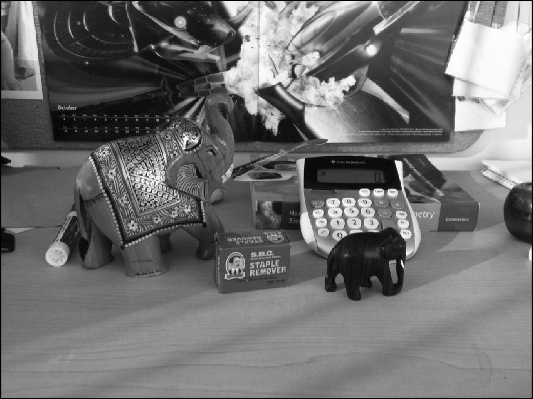

sceneImage = imread("clutteredDesk.jpg");

imshow(sceneImage);
title("Image of a Cluttered Scene");

## Define Target Image

Read the reference image containing the object of interest.

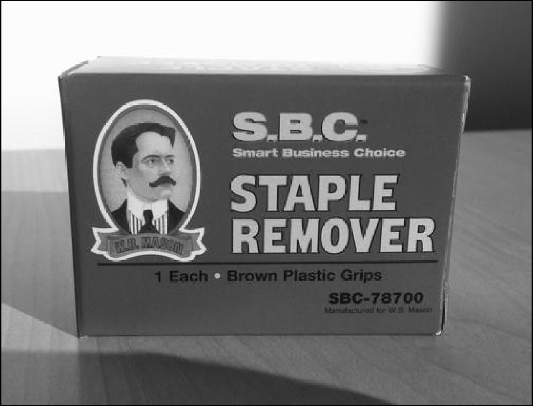

boxImage = imread("stapleRemover.jpg");

imshow(boxImage);
title("Image of a Box");

## Detect Feature Points

Open the Registration Estimator app

%registrationEstimator
boxImage = im2gray(boxImage);
sceneImage = im2gray(sceneImage);

boxPoints = detectSURFFeatures(boxImage);
scenePoints = detectSURFFeatures(sceneImage);

## Visualize the strongest feature points found in the reference and target images.

ax(1) = subplot(1, 2, 1);
imshow(boxImage);
title("100 Strongest Feature Points from Box Image");
hold on;
plot(boxPoints.selectStrongest(100));

Visualize the strongest feature points found in the target image.

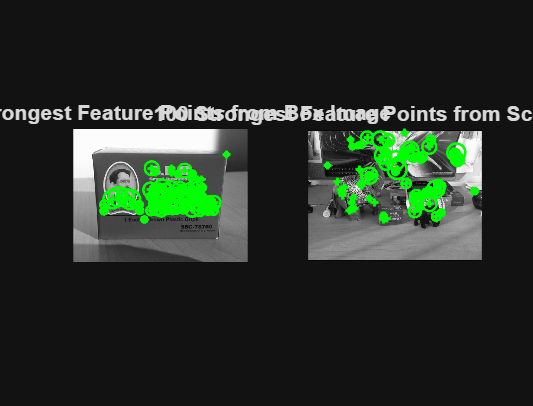

ax(2) = subplot(1, 2, 2);
imshow(sceneImage);
title("100 Strongest Feature Points from Scene Image");
hold on;
plot(scenePoints.selectStrongest(100));

## Extract Feature Descriptors

Extract feature descriptors at the interest points in both images.

[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

## Find Putative Point Matches

Match the features using their descriptors.

boxPairs = matchFeatures(boxFeatures, sceneFeatures);


Display putatively matched features

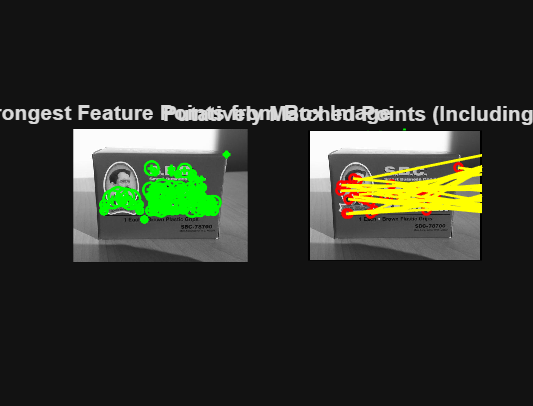

matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);

showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, ...
	matchedScenePoints, "montage");
title("Putatively Matched Points (Including Outliers)");

## Locate the Object in the Scene Using Putative Matches

`estimateGeometricTransform` calculates the transformation relating the matched points, while eliminating outliers. This transformation allows us to localize the objestimateGeometricTransformect in the scene.

matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);

[tform, inlierBoxPoints, inlierScenePoints] = estimateGeometricTransform2D(matchedBoxPoints, ...
    matchedScenePoints, "affine");

## Display the matching point pairs with the outliers removed

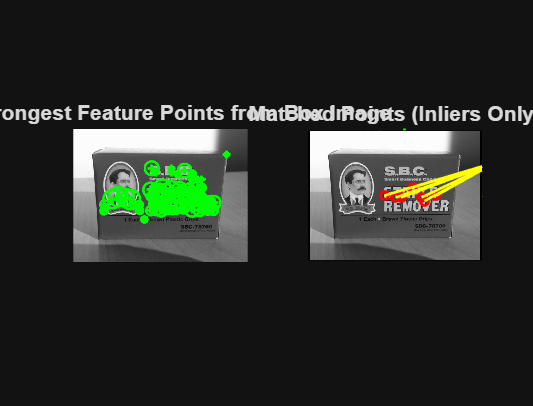

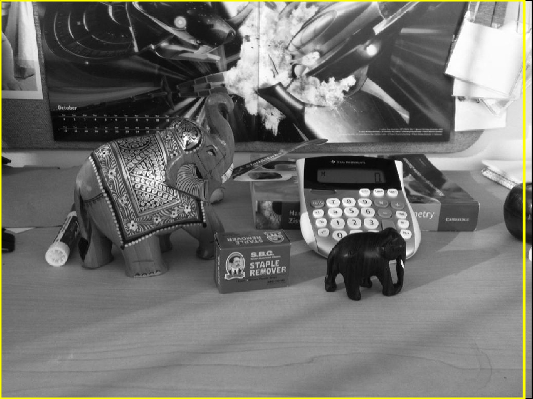

showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints(inlierScenePoints), ...
	matchedScenePoints(inlierScenePoints), "montage");
title("Matched Points (Inliers Only)");